# Tratar os dados

clear

Para o experimento do rodas, descomente a linha a seguir:

% tbl = readtable("Rodas/exp_rodas_bruto.txt");

Para o experimento do corpo, descomente a linha a seguir:

% tbl = readtable("Corpo/exp_corpo_bruto.txt");

%% Convert to output type
t = tbl.t;
u = tbl.u;
yr = -tbl.yr;
yl = tbl.yl;
freq = tbl.freq;
dtheta = -tbl.dtheta;

%% Clear temporary variables
clear tbl

## Normalização

max(u)

ans = 29

uni = max(u)/100 * 7.4;

u = u / max(u);
yr = yr / uni;
yr = yr - mean(yr);
yl = yl / uni;
yl = yl - mean(yl);
dtheta = dtheta / uni;
dtheta = dtheta - mean(dtheta);

## Corrigindo unidades

De pulsos para radianos

yr = yr * 2 * pi / (30 * 4 * 7);
yl = yl * 2 * pi / (30 * 4 * 7);

## Criando variáveis

Velocidade medida pelos encoderes

dyl = gradient(yl) ./ gradient(t);
dyr = gradient(yr) ./ gradient(t);

Posição medida pela IMU

theta = cumtrapz(t, dtheta);
theta = theta - mean(theta);

## Verificar os dados calculados

Criar labels e limites comuns aos gráficos

l_tempo = "Tempo(s)";
l_pos = "Posição(rad)";
l_vel = "Velocidade(rad/s)";
l_frad = "Frequência(rad/s)";
l_gdec = "|G| dB";

limyp = [min(yr) max(yr)];
limyv = [min(dyr) max(dyr)];
limx = [t(1) t(end)];

#### Gráficos de velocidade à esqueda e gráficos de posição à direita

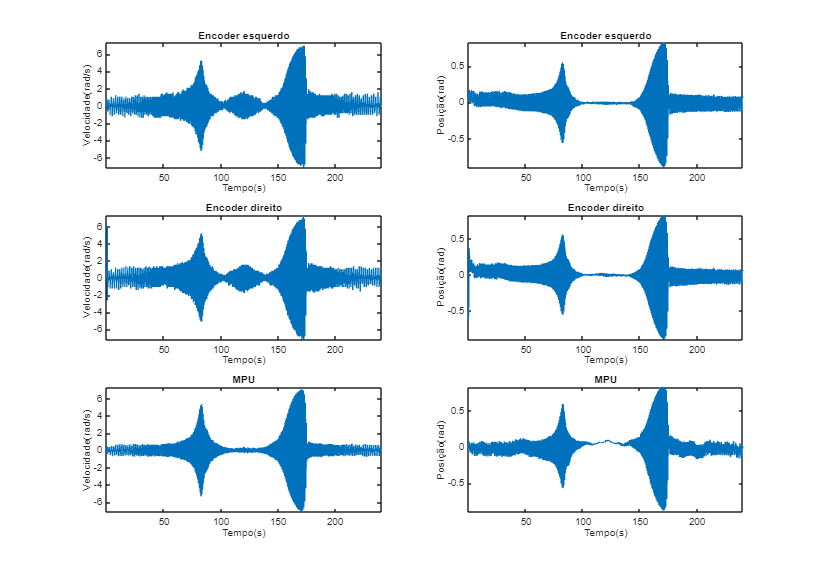

figure("Position", [403 146 1200 840])

subplot(3,2,1); plot(t, dyl);       ylabel(l_vel); xlabel(l_tempo); ylim(limyv); xlim(limx); title("Encoder esquerdo");
subplot(3,2,2); plot(t, yl);        ylabel(l_pos); xlabel(l_tempo); ylim(limyp); xlim(limx); title("Encoder esquerdo");
subplot(3,2,3); plot(t, dyr);       ylabel(l_vel); xlabel(l_tempo); ylim(limyv); xlim(limx); title("Encoder direito");
subplot(3,2,4); plot(t, yr);        ylabel(l_pos); xlabel(l_tempo); ylim(limyp); xlim(limx); title("Encoder direito"); 
subplot(3,2,5); plot(t, dtheta);    ylabel(l_vel); xlabel(l_tempo); ylim(limyv); xlim(limx); title("MPU");
subplot(3,2,6); plot(t, theta);     ylabel(l_pos); xlabel(l_tempo); ylim(limyp); xlim(limx); title("MPU");

clear l_tempo l_pos l_vel l_frad l_gdec limyp limyv limx uni ans

Para o experimento do rodas, descomente a linha a seguir:

% save("Rodas/exp_rodas.mat")

Para o experimento do corpo, descomente a linha a seguir:

% save("Corpo/exp_corpo.mat")